**Explain the two methods to calculate the Volatility - Volat1 and Volat2**

% filter outliers, method applied in volat2
dayprice = reshape(PHSdata.RRP,288,[]);
rmo_price = filloutliers(dayprice,"nearest","median",'ThresholdFactor',7);
daymax2 = max(rmo_price)';
daymin2 = min(rmo_price)';

% hourly mean, method applied in volat1
hourprice = reshape(PHSdata.RRP,opts,[]);
meanprice = mean(hourprice)';
daymax1 = max(reshape(meanprice,288/opts,[]))';
daymin1 = min(reshape(meanprice,288/opts,[]))';

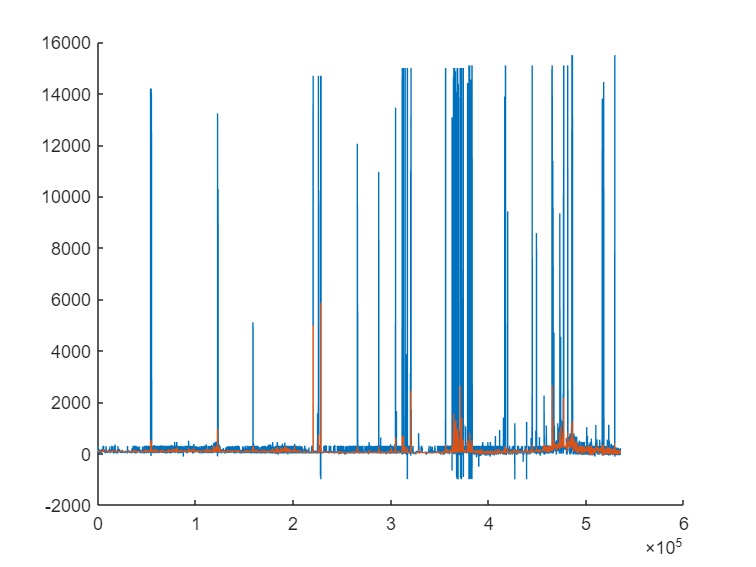

clf; hold on
plot(PHSdata.RRP);
plot(1:24:height(PHSdata),smooth(meanprice,3));

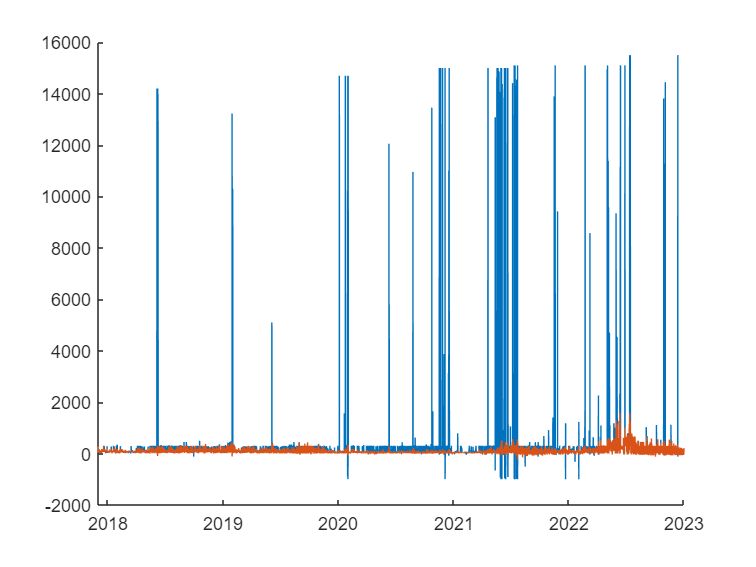

rmo_price_ = reshape(rmo_price,[],1);
clf; hold on
plot(PHSdata.SETTLEMENTDATE,PHSdata.RRP);
plot(PHSdata.SETTLEMENTDATE,rmo_price_);

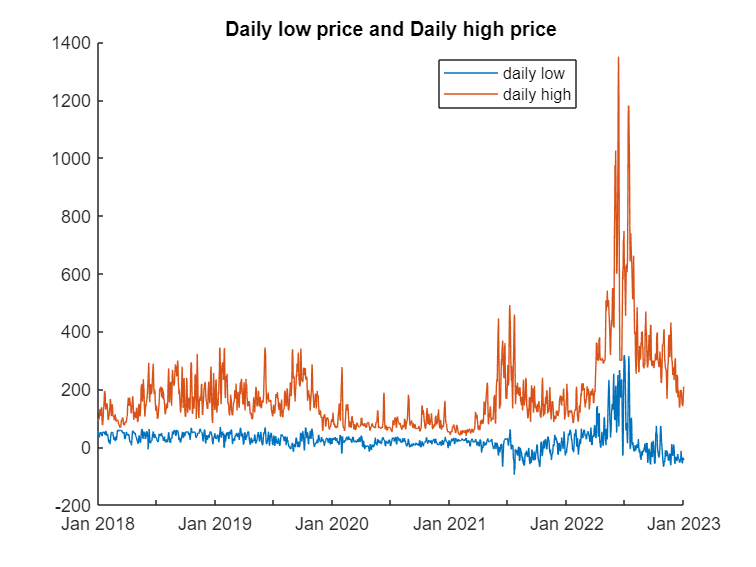

clf; hold on
plot(calcVREdaily.SETTLEMENTDATE,smooth(daymin2(32:end),3));
plot(calcVREdaily.SETTLEMENTDATE,smooth(daymax2(32:end),3));
title("Daily low price and Daily high price")
legend("daily low","daily high")

legend('Position',[0.58085,0.81151,0.18214,0.082143])

**Spread and Net Revenue?**

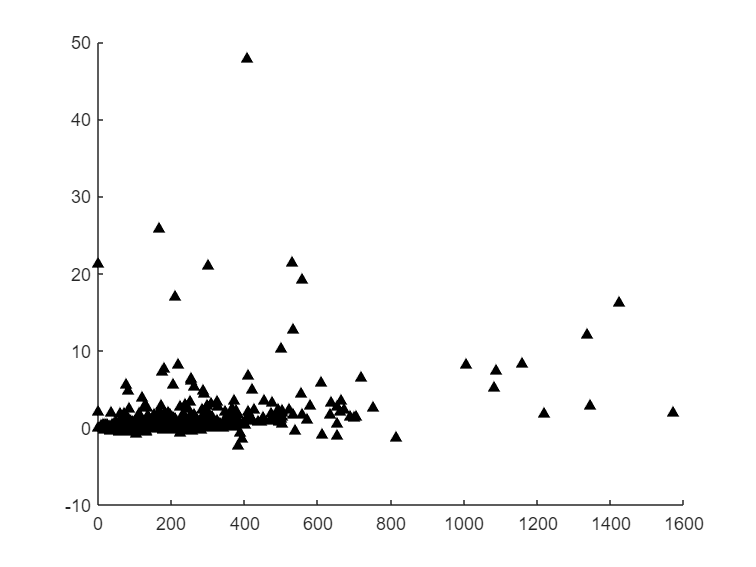

itval = 2; % interval = 7 days
% default 3 times MAD, funcAvrRRP2 use 10 times MAD or so.
[~, ~, v1] = funcAvrRRP2(PHSdata(:,{'SETTLEMENTDATE','RRP'}),start_date,end_date,288*itval);
v1 = v1.Spread;

v2 = (calcPHSdaily.PHSgenAUD-calcPHSdaily.PHSpumpAUD)*1e-6;
v2 = v2(1:end-rem(length(v2),itval));
v2 = sum(reshape(v2,itval,[]))';


clf;
scatter(v1,v2,"black","filled","^")

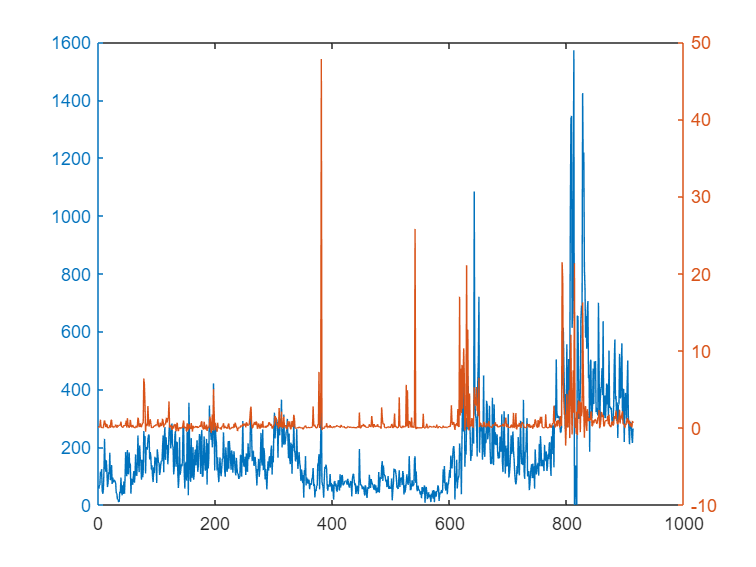

[rho,pval]=corr(v1,v2,type="Spearman");

clf;
yyaxis("left");plot(v1)
% hold on; yline(150)
yyaxis("right");plot(v2)

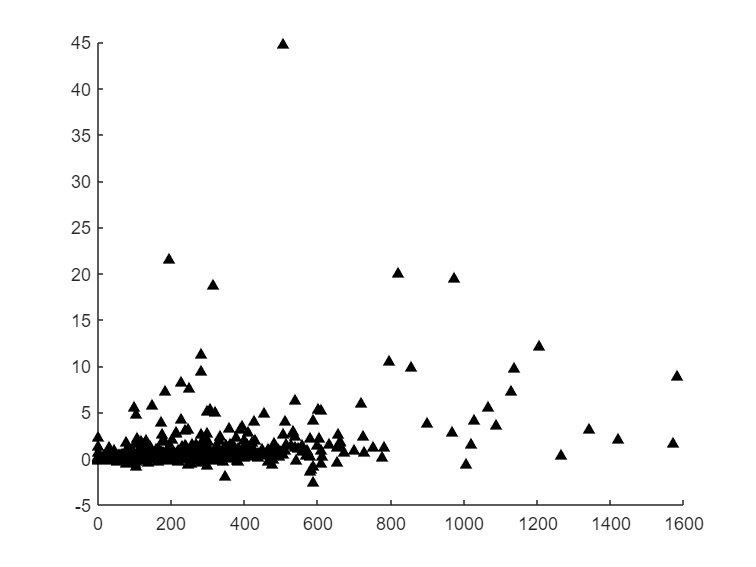

% [~, v1, ~] = funcAvrRRP2(PHSdata(:,{'SETTLEMENTDATE','RRP'}),start_date,end_date,12*2);
% v1 = smooth(v1.Spread,1);

% [v1, ~, ~] = funcAvrRRP2(PHSdata(:,{'SETTLEMENTDATE','RRP'}),start_date,end_date,288);
% v1 = smooth(v1.AvrRRP,1);

[~, ~, v1] = funcAvrRRP2(PHSdata(:,{'SETTLEMENTDATE','RRP'}),start_date,end_date,12*3);
v1 = smooth(v1.Spread,1);

v2 = smooth((calcPHSdaily.PHSgenAUD-calcPHSdaily.PHSpumpAUD)*1e-6,1);


clf;
scatter(v1,v2,"black","filled","^")

corr(v1,v2,type="Spearman")

ans = 0.4342

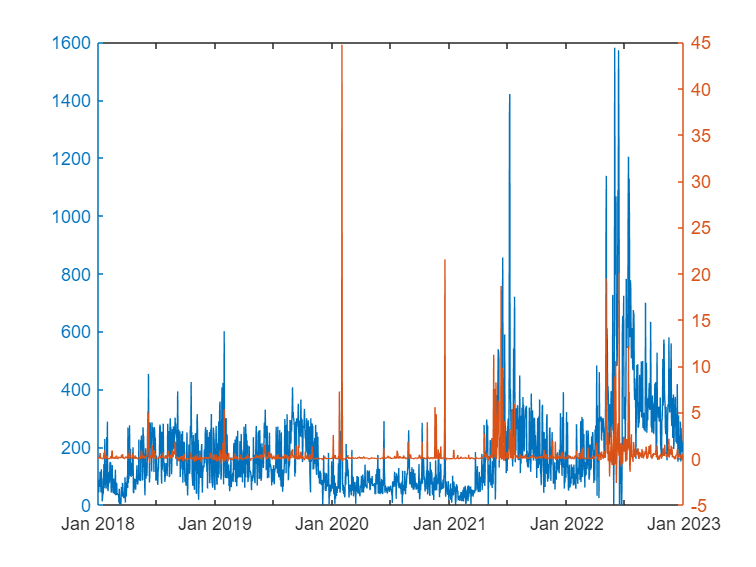


clf;
yyaxis("left");plot(calcPHSdaily.SETTLEMENTDATE,v1)
yyaxis("right");plot(calcPHSdaily.SETTLEMENTDATE,v2)